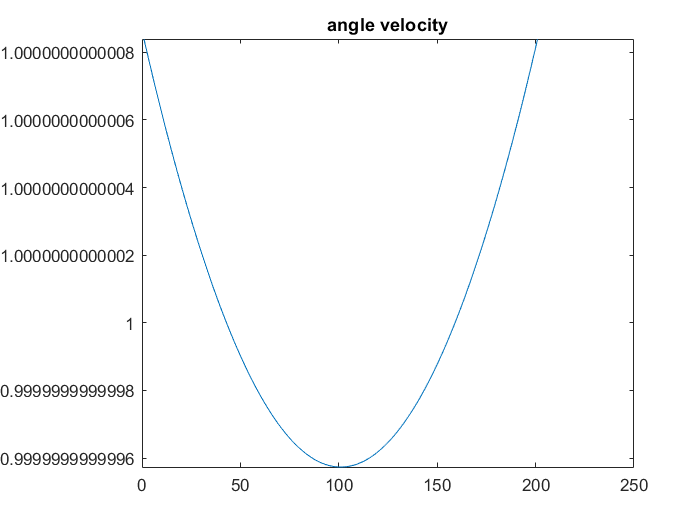

% assume refraction number, n = 3
n = 3;
% unit as lambda, optical frequency:411.0420THz
w0 = 2*pi*411.0420;
T = 2*pi/w0;
r0 = 1;
z = -100:100;
% with The Rayleigh distance or Rayleigh range zR(so that the confocal parameter or depth of focus, the distance between two points z = ±zR, is 2*zR)
% is determined given a Gaussian beam's waist size(Here λ is the wavelength 
% of the light, n is the index of refraction. At a distance from the waist equal to the Rayleigh range zR, the width w of the 
% beam is √2 larger than it is at the focus where w = w0, the beam waist. That also implies that the on-axis (r = 0) intensity
% there is one half of the peak intensity (at z = 0). That point along the beam also happens to be where the wavefront curvature
% (1/R) is greatest.): zR = pi*W0^2*n/lambda;
zR = pi*w0^2*n;
% At position z the Gouy phase of a fundamental Gaussian beam is given by:
phi = atan(z/zR);
% Wavefront curvature radius R
% largest at the Rayleigh distance, z = ±zR, 
% on either side of the waist, crossing zero at the waist itself. 
% Beyond the Rayleigh distance, |z| > zR, it again decreases in magnitude,
% approaching zero as z -> ±∞. The curvature is often expressed in terms of its reciprocal,
% R, the radius of curvature; for a fundamental(TEM00) Gaussian beam the curvature at position z is given by
R = z.*(1+(zR*ones(size(z))/z).^2);%?why.
%R = z*(1+(zR/z)^2);
%evolving beam width
w = w0*sqrt(1+(z/zR).^2);
plot(w/mean(w));
title('angle velocity')

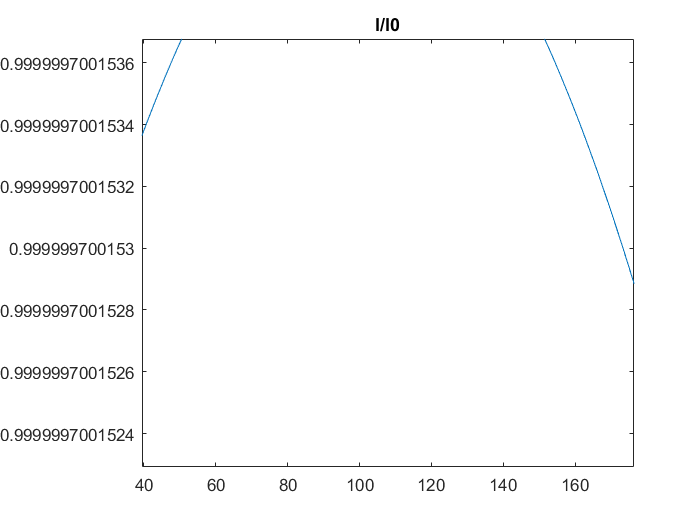

T = 2*pi./w;
% Gaussian laser beam: I/I0 = (w0/w)^2*exp(-2*r^2/w^2);
IrI0 = (w0./w).^2.*exp(-2.*r0.^2./w.^2);
plot(IrI0);
title('I/I0');

I = (w0./w).^2.*exp(-2.*r0.^2./w.^2);

%     t = 1:50;
%     y = t+normpdf(t);
%     alpha = ones(size(t));
%     alpha([1 3 end]) = 100;
%     Bout = spap2(1, 2, t, y, alpha); 
%     kk = Bout.order;
Delta = z;
Phi = z;
Delta0 = z;
Phi0 = z;
Res = 10^10;
% consider the rabi oscillation, consider a spin-1/2 system with magnetic
% moment mu placed in a classical magnetic field B =
% B0*z+B1*(cos(wt)*x-sin(w*t)*y). Let gamma be the gyromagnetic ratio for
% the system. The magnetic moment is thus mu = h*gamma*sigma/4/pi
for t = 1:(length(z)-1)
    %Hamiltonian of this system is then given by: H = -mu*B =
    %-h/4*w0*sigmaz/pi-h/w1*(sigmax*coswt-sigmay*sinwt),with pi/2 pulse
    w1 = pi/2/t;
    Phi0(t) = 1/w1;
    Delta0(t) = w0;
    k = w(t)*t;
    %Rabi frequency, Phi and laser phase, phi varies with time
    %laser wave vector k(t) projected onto the transport axis 
    % at position z(t) and wL, the laser frequency
    % The spatial variation of kz(z(t))
    % accounts for the curvature of the wavefronts of 
    % the Gaussian laser beam: 
    h = 6.62607015*10^(-34);
    phi = k*z(t);%k = abs(k)*cos(theta);    
    %dephi = (k(2:end)-k(1:end-1))./(z(2:end)-z(1:end-1))*z+k;
    dephi = (w(t+1)*(t+1)-k)/(z(t+1)-z(t))*z(t)+k;
    Phi(t) = phi - w(t)*t;
    deltaL = w(t) - w0;
    Delta(t) = deltaL - dephi; %detuning
    H(t,:) = h/4/pi*(-Phi(t)*PX+Delta(t)*PZ);
    if t == length(z)-1
        Phi(t+1) = phi*(t+1);
        deltaL = w(t+1) - w0;
        Delta(t+1) = deltaL - dephi; %detuning
        H(t+1,:) = h/4/pi*(-Phi(t+1)*PX+Delta(t+1)*PZ);
    end
end


c = 0;
% find best knots
for kn = 2:length(Phi0)
    BPhi = spap2(augknt([Phi0(1),Phi0(1)+(Phi0(end)-Phi0(1))/(kn-1):(Phi0(end)-Phi0(1))/(kn-1):Phi0(end)-(Phi0(end)-Phi0(1))/(kn-1),Phi0(end)],kn),kn,Phi0,Phi);
%    BDelta = spap2(augknt([Delta0(1),Delta0(1)+(Delta0(end)-Delta0(1))/(kn-1):(Delta0(end)-Delta0(1))/(kn-1):Delta0(end)-(Delta0(end)-Delta0(1))/(kn-1),Delta0(end)],kn),kn,Delta0,Delta);
%    BDelta = spap2(kn+1,1,Delta0,Delta);
    if sum(isnan(BPhi.knots))+sum(isnan(BPhi.coefs))>0
        break
    else
        if length(unique(BPhi.knots)) == BPhi.number/2 + 1
            BPhi.knots = unique(BPhi.knots);
        end
            Phifit0 = BPhi.knots(1:BPhi.order:end).*BPhi.coefs(1:BPhi.order/2:end);
%        Phifit1 = interp1(Phifit0,1:0.5:length(Phifit0))./BPhi.coefs;
        Phiref = Phi(floor(length(Phi0)/BPhi.number):floor(length(Phi0)/BPhi.number):length(Phi0));
        Phiref =  Phiref(1:length(BPhi.coefs))
        %         Deltafit0 = BDelta.knots(1:BDelta.order:end).*BDelta.coefs(1:BDelta.order/2:end);
% %        Phifit1 = interp1(Phifit0,1:0.5:length(Phifit0))./BPhi.coefs;
%         Deltaref = Delta(floor(length(Delta0)/BDelta.number):floor(length(Delta0)/BDelta.number):length(Delta0));
        if length(Phifit0)==BPhi.number
            Phifit = abs(Phifit0).*(sign(Phiref))
        else
            if BPhi.number == length(1:(length(Phifit0)-0.5)/BPhi.number:length(Phifit0))
                Phifit =abs(interp1(Phifit0,1:(length(Phifit0)-0.5)/BPhi.number:length(Phifit0))./sqrt(abs(BPhi.coefs/Phi0(end)^(length(Phifit0)-BPhi.number)))).*(sign(Phiref));
            elseif BPhi.number == length(interp1(Phifit0,1:length(Phifit0)/(BPhi.number+0.5):length(Phifit0)))
                Phifit =abs(interp1(Phifit0,1:length(Phifit0)/(BPhi.number+0.5):length(Phifit0))./sqrt(abs(BPhi.coefs/Phi0(end)^(length(Phifit0)-BPhi.number)))).*(sign(Phiref));
            elseif BPhi.number == length(interp1(Phifit0,1:length(Phifit0)/(BPhi.number+1):length(Phifit0)))
                Phifit =abs(interp1(Phifit0,1:length(Phifit0)/(BPhi.number+1):length(Phifit0))./sqrt(abs(BPhi.coefs/Phi0(end)^(length(Phifit0)-BPhi.number)))).*(sign(Phiref));
            elseif BPhi.number == length(interp1(Phifit0,1:(length(Phifit0)-0.5)/(BPhi.number+0.5):length(Phifit0)))
                Phifit =abs(interp1(Phifit0,1:(length(Phifit0)-0.5)/(BPhi.number+0.5):length(Phifit0))./sqrt(abs(BPhi.coefs/Phi0(end)^(length(Phifit0)-BPhi.number)))).*(sign(Phiref));                            
            elseif BPhi.number == length(interp1(Phifit0,1:(length(Phifit0)-1)/BPhi.number:length(Phifit0)))
                Phifit =abs(interp1(Phifit0,1:(length(Phifit0)-1)/BPhi.number:length(Phifit0))./sqrt(abs(BPhi.coefs/Phi0(end)^(length(Phifit0)-BPhi.number)))).*(sign(Phiref));
            else
                InterpT = interp1(Phifit0,1:(length(Phifit0)-1)/BPhi.number:length(Phifit0));
                Phifit = abs(InterpT(1:length(Phiref))./sqrt(abs(BPhi.coefs/Phi0(end)^(length(Phifit0)-BPhi.number)))).*(sign(Phiref));
            end
        end
%         if length(Deltafit0)==BDelta.number
%             Deltafit = abs(Deltafit0).*(sign(Deltaref))
%         else
%             if BDelta.number == length(1:(length(Deltafit0)-0.5)/BDelta.number:length(Deltafit0))
%                 Deltafit =abs(interp1(Deltafit0,1:(length(Deltafit0)-0.5)/BDelta.number:length(Deltafit0))./sqrt(abs(BDelta.coefs/Delta0(end)^(length(Deltafit0)-BDelta.number)))).*(sign(Deltaref));
%             elseif BDelta.number == length(interp1(Deltafit0,1:(length(Deltafit0)-0.5)/(BDelta.number+0.5):length(Deltafit0)))
%                 Deltafit =abs(interp1(Deltafit0,1:(length(Deltafit0)-0.5)/(BDelta.number+0.5):length(Deltafit0))./sqrt(abs(BDelta.coefs/Delta0(end)^(length(Deltafit0)-BDelta.number)))).*(sign(Deltaref));                            
%             elseif BDelta.number == length(interp1(Deltafit0,1:(length(Deltafit0)-1)/BDelta.number:length(Deltafit0)))
%                 Deltafit =abs(interp1(Deltafit0,1:(length(Deltafit0)-1)/BDelta.number:length(Deltafit0))./sqrt(abs(BDelta.coefs/Delta0(end)^(length(Deltafit0)-BDelta.number)))).*(sign(Deltaref));
%             end
%         end        
        res = mean(abs(Phifit) - abs(Phiref)) %+ mean(abs(Deltafit)-abs(Deltaref));
    end
    if abs(Res) > abs(res)
       c = c +1;
       Res = res;
       RES(c) = Res;
       PHI(c) = mean(Phifit);
       PHIREF(c) = mean(Phiref);  
%        DELTA(c) = Deltafit;
%        DELTAREF(c) = Deltaref; 
       dt(c) = length(Delta)/length(Deltafit);
%        Hs(c,:) = h/4/pi*(-PHI(c)*PX+DELTA(c)*PZ);       
%        Hsref(c,:) = h/4/pi*(-PHIREF(c)*PX+DELTAREF(c)*PZ);
        Hs(c,:) = h/4/pi*(-PHI(c)*PX + Delta0(c)*PZ);       
        Hsref(c,:) = h/4/pi*(-PHIREF(c)*PX+Delta(c)*PZ);
    end
end

Phiref = 	1.0e+07 *

   -0.0517    5.0620


Phifit = 	1.0e+08 *

   -0.8658    1.6870


res = 1.0207e+08

Phiref = 	1.0e+07 *

   -0.6715   -0.0517    1.8595    5.0620


res = -1.9111e+07

Phiref = 	1.0e+07 *

   -0.5881   -0.6136   -0.0767    1.0227    2.6847    4.9091


res = -1.6492e+07

Phiref = 	1.0e+07 *

   -0.4972   -0.6715   -0.5230   -0.0517    0.7425    1.8595    3.2993    5.0620


res = -1.5883e+07

Phiref = 	1.0e+07 *

   -0.4236   -0.6405   -0.6508   -0.4545   -0.0517    0.5579    1.3740    2.3967    3.6260    5.0620


res = -1.5238e+07

Phiref = 	1.0e+07 *

   -0.3554   -0.5785   -0.6694   -0.6281   -0.4545   -0.1488    0.2893    0.8595    1.5620    2.3967    3.3636    4.4628


res = -1.3141e+07

Phiref = 	1.0e+07 *

   -0.3182   -0.5351   -0.6508   -0.6653   -0.5785   -0.3905   -0.1012    0.2893    0.7810    1.3740    2.0682    2.8636    3.7603    4.7583


res = -1.3667e+07

Phiref = 	1.0e+07 *

   -0.2789   -0.4835   -0.6136   -0.6694   -0.6508   -0.5579   -0.3905   -0.1488    0.1674    0.5579    1.0227    1.5620    2.1756    2.8636    3.6260    4.4628


res = -1.2645e+07

Phiref = 	1.0e+07 *

   -0.2585   -0.4545   -0.5881   -0.6591   -0.6676   -0.6136   -0.4972   -0.3182   -0.0767    0.2273    0.5938    1.0227    1.5142    2.0682    2.6847    3.3636    4.1051    4.9091


res = -1.3679e+07

Phiref = 	1.0e+07 *

   -0.2376   -0.4236   -0.5579   -0.6405   -0.6715   -0.6508   -0.5785   -0.4545   -0.2789   -0.0517    0.2273    0.5579    0.9401    1.3740    1.8595    2.3967    2.9855    3.6260    4.3182    5.0620


res = -1.3946e+07

Phiref = 	1.0e+07 *

   -0.2162   -0.3905   -0.5230   -0.6136   -0.6625   -0.6694   -0.6346   -0.5579   -0.4393   -0.2789   -0.0767    0.1674    0.4533    0.7810    1.1506    1.5620    2.0152    2.5103    3.0473    3.6260    4.2467    4.9091


res = -1.3423e+07

Phiref = 	1.0e+07 *

   -0.1942   -0.3554   -0.4835   -0.5785   -0.6405   -0.6694   -0.6653   -0.6281   -0.5579   -0.4545   -0.3182   -0.1488    0.0537    0.2893    0.5579    0.8595    1.1942    1.5620    1.9628    2.3967    2.8636    3.3636    3.8967    4.4628


res = -1.2149e+07

Phiref = 	1.0e+07 *

   -0.1717   -0.3182   -0.4393   -0.5351   -0.6056   -0.6508   -0.6707   -0.6653   -0.6346   -0.5785   -0.4972   -0.3905   -0.2585   -0.1012    0.0814    0.2893    0.5225    0.7810    1.0648    1.3740    1.7084    2.0682    2.4533    2.8636    3.2993    3.7603


res = -1.0301e+07

Phiref = 	1.0e+07 *

   -0.1717   -0.3182   -0.4393   -0.5351   -0.6056   -0.6508   -0.6707   -0.6653   -0.6346   -0.5785   -0.4972   -0.3905   -0.2585   -0.1012    0.0814    0.2893    0.5225    0.7810    1.0648    1.3740    1.7084    2.0682    2.4533    2.8636    3.2993    3.7603    4.2467    4.7583


res = -1.2782e+07

Phiref = 	1.0e+07 *

   -0.1488   -0.2789   -0.3905   -0.4835   -0.5579   -0.6136   -0.6508   -0.6694   -0.6694   -0.6508   -0.6136   -0.5579   -0.4835   -0.3905   -0.2789   -0.1488         0    0.1674    0.3533    0.5579    0.7810    1.0227    1.2831    1.5620    1.8595    2.1756    2.5103    2.8636    3.2355    3.6260


res = -9.8616e+06

Phiref = 	1.0e+07 *

   -0.1488   -0.2789   -0.3905   -0.4835   -0.5579   -0.6136   -0.6508   -0.6694   -0.6694   -0.6508   -0.6136   -0.5579   -0.4835   -0.3905   -0.2789   -0.1488         0    0.1674    0.3533    0.5579    0.7810    1.0227    1.2831    1.5620    1.8595    2.1756    2.5103    2.8636    3.2355    3.6260    4.0351    4.4628


res = -1.1901e+07

Phiref = 	1.0e+07 *

   -0.1253   -0.2376   -0.3370   -0.4236   -0.4972   -0.5579   -0.6056   -0.6405   -0.6625   -0.6715   -0.6676   -0.6508   -0.6211   -0.5785   -0.5230   -0.4545   -0.3732   -0.2789   -0.1717   -0.0517    0.0814    0.2273    0.3861    0.5579    0.7425    0.9401    1.1506    1.3740    1.6103    1.8595    2.1216    2.3967    2.6847    2.9855


res = -8.3082e+06

Phiref = 	1.0e+07 *

   -0.1253   -0.2376   -0.3370   -0.4236   -0.4972   -0.5579   -0.6056   -0.6405   -0.6625   -0.6715   -0.6676   -0.6508   -0.6211   -0.5785   -0.5230   -0.4545   -0.3732   -0.2789   -0.1717   -0.0517    0.0814    0.2273    0.3861    0.5579    0.7425    0.9401    1.1506    1.3740    1.6103    1.8595    2.1216    2.3967    2.6847    2.9855    3.2993    3.6260


res = -9.7703e+06

Phiref = 	1.0e+07 *

   -0.1253   -0.2376   -0.3370   -0.4236   -0.4972   -0.5579   -0.6056   -0.6405   -0.6625   -0.6715   -0.6676   -0.6508   -0.6211   -0.5785   -0.5230   -0.4545   -0.3732   -0.2789   -0.1717   -0.0517    0.0814    0.2273    0.3861    0.5579    0.7425    0.9401    1.1506    1.3740    1.6103    1.8595    2.1216    2.3967    2.6847    2.9855    3.2993    3.6260    3.9657    4.3182


res = -1.1436e+07

Phiref = 	1.0e+07 *

   -0.1253   -0.2376   -0.3370   -0.4236   -0.4972   -0.5579   -0.6056   -0.6405   -0.6625   -0.6715   -0.6676   -0.6508   -0.6211   -0.5785   -0.5230   -0.4545   -0.3732   -0.2789   -0.1717   -0.0517    0.0814    0.2273    0.3861    0.5579    0.7425    0.9401    1.1506    1.3740    1.6103    1.8595    2.1216    2.3967    2.6847    2.9855    3.2993    3.6260    3.9657    4.3182    4.6836    5.0620


res = -1.3301e+07

Phiref = 	1.0e+07 *

   -0.1012   -0.1942   -0.2789   -0.3554   -0.4236   -0.4835   -0.5351   -0.5785   -0.6136   -0.6405   -0.6591   -0.6694   -0.6715   -0.6653   -0.6508   -0.6281   -0.5971   -0.5579   -0.5103   -0.4545   -0.3905   -0.3182   -0.2376   -0.1488   -0.0517    0.0537    0.1674    0.2893    0.4194    0.5579    0.7045    0.8595    1.0227    1.1942    1.3740    1.5620    1.7583    1.9628    2.1756    2.3967    2.6260    2.8636


res = -7.9531e+06

Phiref = 	1.0e+07 *

   -0.1012   -0.1942   -0.2789   -0.3554   -0.4236   -0.4835   -0.5351   -0.5785   -0.6136   -0.6405   -0.6591   -0.6694   -0.6715   -0.6653   -0.6508   -0.6281   -0.5971   -0.5579   -0.5103   -0.4545   -0.3905   -0.3182   -0.2376   -0.1488   -0.0517    0.0537    0.1674    0.2893    0.4194    0.5579    0.7045    0.8595    1.0227    1.1942    1.3740    1.5620    1.7583    1.9628    2.1756    2.3967    2.6260    2.8636    3.1095    3.3636


res = -9.0628e+06

Phiref = 	1.0e+07 *

   -0.1012   -0.1942   -0.2789   -0.3554   -0.4236   -0.4835   -0.5351   -0.5785   -0.6136   -0.6405   -0.6591   -0.6694   -0.6715   -0.6653   -0.6508   -0.6281   -0.5971   -0.5579   -0.5103   -0.4545   -0.3905   -0.3182   -0.2376   -0.1488   -0.0517    0.0537    0.1674    0.2893    0.4194    0.5579    0.7045    0.8595    1.0227    1.1942    1.3740    1.5620    1.7583    1.9628    2.1756    2.3967    2.6260    2.8636    3.1095    3.3636    3.6260    3.8967


res = -1.0304e+07

Phiref = 	1.0e+07 *

   -0.1012   -0.1942   -0.2789   -0.3554   -0.4236   -0.4835   -0.5351   -0.5785   -0.6136   -0.6405   -0.6591   -0.6694   -0.6715   -0.6653   -0.6508   -0.6281   -0.5971   -0.5579   -0.5103   -0.4545   -0.3905   -0.3182   -0.2376   -0.1488   -0.0517    0.0537    0.1674    0.2893    0.4194    0.5579    0.7045    0.8595    1.0227    1.1942    1.3740    1.5620    1.7583    1.9628    2.1756    2.3967    2.6260    2.8636    3.1095    3.3636    3.6260    3.8967    4.1756    4.4628


res = -1.1674e+07

Phiref = 	1.0e+07 *

   -0.1012   -0.1942   -0.2789   -0.3554   -0.4236   -0.4835   -0.5351   -0.5785   -0.6136   -0.6405   -0.6591   -0.6694   -0.6715   -0.6653   -0.6508   -0.6281   -0.5971   -0.5579   -0.5103   -0.4545   -0.3905   -0.3182   -0.2376   -0.1488   -0.0517    0.0537    0.1674    0.2893    0.4194    0.5579    0.7045    0.8595    1.0227    1.1942    1.3740    1.5620    1.7583    1.9628    2.1756    2.3967    2.6260    2.8636    3.1095    3.3636    3.6260    3.8967    4.1756    4.4628    4.7583    5.0620


res = -1.3172e+07

Phiref = 	1.0e+07 *

   -0.0767   -0.1488   -0.2162   -0.2789   -0.3370   -0.3905   -0.4393   -0.4835   -0.5230   -0.5579   -0.5881   -0.6136   -0.6346   -0.6508   -0.6625   -0.6694   -0.6717   -0.6694   -0.6625   -0.6508   -0.6346   -0.6136   -0.5881   -0.5579   -0.5230   -0.4835   -0.4393   -0.3905   -0.3370   -0.2789   -0.2162   -0.1488   -0.0767         0    0.0814    0.1674    0.2580    0.3533    0.4533    0.5579    0.6671    0.7810    0.8995    1.0227    1.1506    1.2831    1.4202    1.5620    1.7084    1.8595


res = -6.4672e+06

Phiref = 	1.0e+07 *

   -0.0767   -0.1488   -0.2162   -0.2789   -0.3370   -0.3905   -0.4393   -0.4835   -0.5230   -0.5579   -0.5881   -0.6136   -0.6346   -0.6508   -0.6625   -0.6694   -0.6717   -0.6694   -0.6625   -0.6508   -0.6346   -0.6136   -0.5881   -0.5579   -0.5230   -0.4835   -0.4393   -0.3905   -0.3370   -0.2789   -0.2162   -0.1488   -0.0767         0    0.0814    0.1674    0.2580    0.3533    0.4533    0.5579    0.6671    0.7810    0.8995    1.0227    1.1506    1.2831    1.4202    1.5620    1.7084    1.8595


res = -7.1260e+06

Phiref = 	1.0e+07 *

   -0.0767   -0.1488   -0.2162   -0.2789   -0.3370   -0.3905   -0.4393   -0.4835   -0.5230   -0.5579   -0.5881   -0.6136   -0.6346   -0.6508   -0.6625   -0.6694   -0.6717   -0.6694   -0.6625   -0.6508   -0.6346   -0.6136   -0.5881   -0.5579   -0.5230   -0.4835   -0.4393   -0.3905   -0.3370   -0.2789   -0.2162   -0.1488   -0.0767         0    0.0814    0.1674    0.2580    0.3533    0.4533    0.5579    0.6671    0.7810    0.8995    1.0227    1.1506    1.2831    1.4202    1.5620    1.7084    1.8595


res = -7.8622e+06

Phiref = 	1.0e+07 *

   -0.0767   -0.1488   -0.2162   -0.2789   -0.3370   -0.3905   -0.4393   -0.4835   -0.5230   -0.5579   -0.5881   -0.6136   -0.6346   -0.6508   -0.6625   -0.6694   -0.6717   -0.6694   -0.6625   -0.6508   -0.6346   -0.6136   -0.5881   -0.5579   -0.5230   -0.4835   -0.4393   -0.3905   -0.3370   -0.2789   -0.2162   -0.1488   -0.0767         0    0.0814    0.1674    0.2580    0.3533    0.4533    0.5579    0.6671    0.7810    0.8995    1.0227    1.1506    1.2831    1.4202    1.5620    1.7084    1.8595


res = -8.6744e+06

Phiref = 	1.0e+07 *

   -0.0767   -0.1488   -0.2162   -0.2789   -0.3370   -0.3905   -0.4393   -0.4835   -0.5230   -0.5579   -0.5881   -0.6136   -0.6346   -0.6508   -0.6625   -0.6694   -0.6717   -0.6694   -0.6625   -0.6508   -0.6346   -0.6136   -0.5881   -0.5579   -0.5230   -0.4835   -0.4393   -0.3905   -0.3370   -0.2789   -0.2162   -0.1488   -0.0767         0    0.0814    0.1674    0.2580    0.3533    0.4533    0.5579    0.6671    0.7810    0.8995    1.0227    1.1506    1.2831    1.4202    1.5620    1.7084    1.8595


res = -9.5610e+06

Phiref = 	1.0e+07 *

   -0.0767   -0.1488   -0.2162   -0.2789   -0.3370   -0.3905   -0.4393   -0.4835   -0.5230   -0.5579   -0.5881   -0.6136   -0.6346   -0.6508   -0.6625   -0.6694   -0.6717   -0.6694   -0.6625   -0.6508   -0.6346   -0.6136   -0.5881   -0.5579   -0.5230   -0.4835   -0.4393   -0.3905   -0.3370   -0.2789   -0.2162   -0.1488   -0.0767         0    0.0814    0.1674    0.2580    0.3533    0.4533    0.5579    0.6671    0.7810    0.8995    1.0227    1.1506    1.2831    1.4202    1.5620    1.7084    1.8595


res = -1.0521e+07

Phiref = 	1.0e+07 *

   -0.0767   -0.1488   -0.2162   -0.2789   -0.3370   -0.3905   -0.4393   -0.4835   -0.5230   -0.5579   -0.5881   -0.6136   -0.6346   -0.6508   -0.6625   -0.6694   -0.6717   -0.6694   -0.6625   -0.6508   -0.6346   -0.6136   -0.5881   -0.5579   -0.5230   -0.4835   -0.4393   -0.3905   -0.3370   -0.2789   -0.2162   -0.1488   -0.0767         0    0.0814    0.1674    0.2580    0.3533    0.4533    0.5579    0.6671    0.7810    0.8995    1.0227    1.1506    1.2831    1.4202    1.5620    1.7084    1.8595


res = -1.1553e+07

Phiref = 	1.0e+07 *

   -0.0767   -0.1488   -0.2162   -0.2789   -0.3370   -0.3905   -0.4393   -0.4835   -0.5230   -0.5579   -0.5881   -0.6136   -0.6346   -0.6508   -0.6625   -0.6694   -0.6717   -0.6694   -0.6625   -0.6508   -0.6346   -0.6136   -0.5881   -0.5579   -0.5230   -0.4835   -0.4393   -0.3905   -0.3370   -0.2789   -0.2162   -0.1488   -0.0767         0    0.0814    0.1674    0.2580    0.3533    0.4533    0.5579    0.6671    0.7810    0.8995    1.0227    1.1506    1.2831    1.4202    1.5620    1.7084    1.8595


res = -1.2656e+07

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -4.8141e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -5.0561e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -5.3363e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -5.6539e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -6.0081e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -6.3981e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -6.8234e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -7.2833e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -7.7775e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -8.3053e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -8.8665e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -9.4605e+06

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -1.0087e+07

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -1.0746e+07

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -1.1437e+07

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -1.2159e+07

Phiref = 	1.0e+07 *

   -0.0517   -0.1012   -0.1488   -0.1942   -0.2376   -0.2789   -0.3182   -0.3554   -0.3905   -0.4236   -0.4545   -0.4835   -0.5103   -0.5351   -0.5579   -0.5785   -0.5971   -0.6136   -0.6281   -0.6405   -0.6508   -0.6591   -0.6653   -0.6694   -0.6715   -0.6715   -0.6694   -0.6653   -0.6591   -0.6508   -0.6405   -0.6281   -0.6136   -0.5971   -0.5785   -0.5579   -0.5351   -0.5103   -0.4835   -0.4545   -0.4236   -0.3905   -0.3554   -0.3182   -0.2789   -0.2376   -0.1942   -0.1488   -0.1012   -0.0517


res = -1.2913e+07

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.4779e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.3995e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.3345e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.2825e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.2432e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.2163e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.2015e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.1985e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.2071e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.2270e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.2580e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.3000e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.3526e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.4158e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.4894e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.5732e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.6670e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.7708e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -4.8844e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -5.0076e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -5.1404e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -5.2826e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -5.4342e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -5.5950e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -5.7649e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -5.9439e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -6.1319e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -6.3288e+06

Phiref =    -0.2608   -0.5165   -0.7670   -1.0124   -1.2526   -1.4876   -1.7175   -1.9422   -2.1617   -2.3760   -2.5852   -2.7893   -2.9881   -3.1818   -3.3704   -3.5537   -3.7319   -3.9050   -4.0728   -4.2356   -4.3931   -4.5455   -4.6927   -4.8347   -4.9716   -5.1033   -5.2299   -5.3513   -5.4675   -5.5785


res = -6.5344e+06

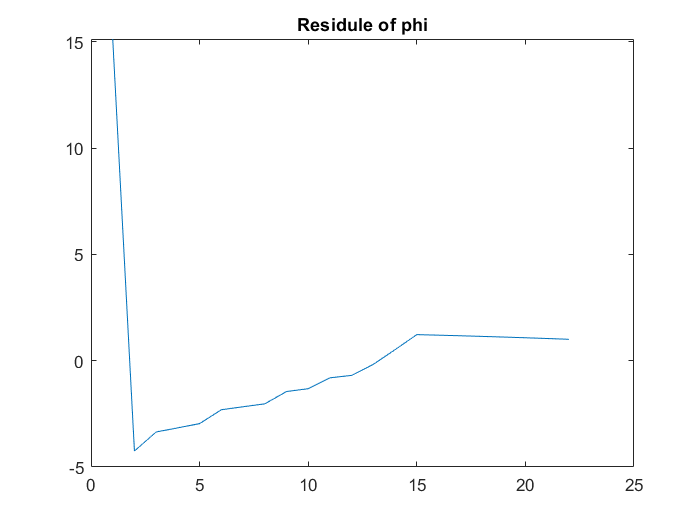

PHI = PHI/mean(PHI);
PHIREF = PHIREF/mean(PHIREF);   
meanPHI = PHI;
meanPHIREF = PHIREF;
CVPHI = PHI;
CVPHIREF = PHIREF;

for ti = 1: length(c)
    meanPHI(ti) = mean(PHI(1:ti));
    stdPHI(ti) = std(PHI(1:ti));
    CVPHI(ti) = meanPHI(ti)/stdPHI(ti);  

    meanPHIREF(ti) = mean(PHIREF(1:ti));
    stdPHIREF(ti) = std(PHIREF(1:ti));
    CVPHIREF(ti) = meanPHIREF(ti)/stdPHIREF(ti);  
end
meanRES = meanPHI - meanPHIREF;
stdRES = stdPHI - stdPHIREF;
CVRES = CVPHI - CVPHIREF;

plot(meanRES)
title('Residule of phi')

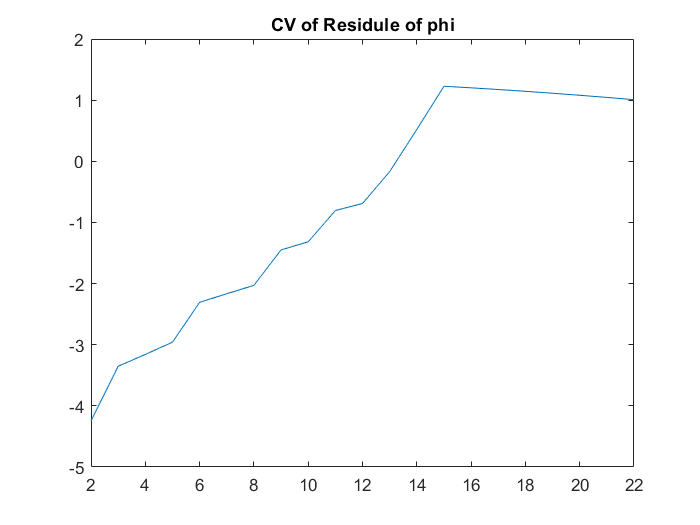

plot(CVRES)
title('CV of Residule of phi')


[h1,p1,ci1,stats1] = ttest(meanPHI, meanPHIREF)

h1 = 0

p1 = 1.0000

ci1 =    -1.6941    1.6941


stats1 = struct with fields:
    tstat: -4.7081e-16
       df: 21
       sd: 3.8209



[h2,p2,ci2,stats2] = ttest(Hs, Hsref)

h2 =      1     0     0     1


p2 =     0.0000    0.2848    0.2848    0.0000


ci2 =    -0.0113   -0.0841   -0.0841    0.0097
   -0.0097    0.2721    0.2721    0.0113


stats2 = struct with fields:
    tstat: [-27.8091 1.0975 1.0975 27.8091]
       df: [21 21 21 21]
       sd: [1.7686e-30 4.0167e-28 4.0167e-28 1.7686e-30]



%imagesc(Hs./Hsref);